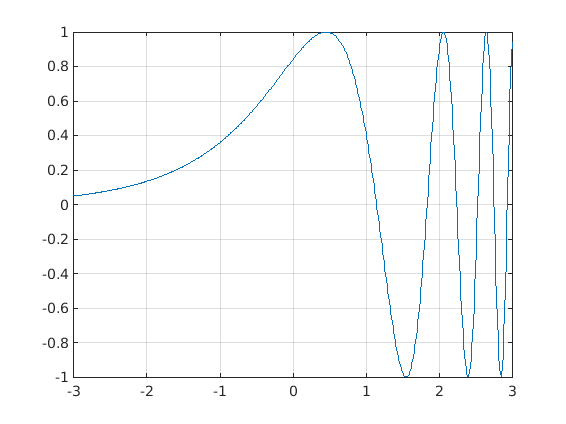

% a
x = -3:0.01:3;
y = sin(exp(x));
plot(x,y);
grid on;

z = ginput(1);


r = fzero(@(x) sin(exp(x)), z(1));
disp(r);

    1.1447



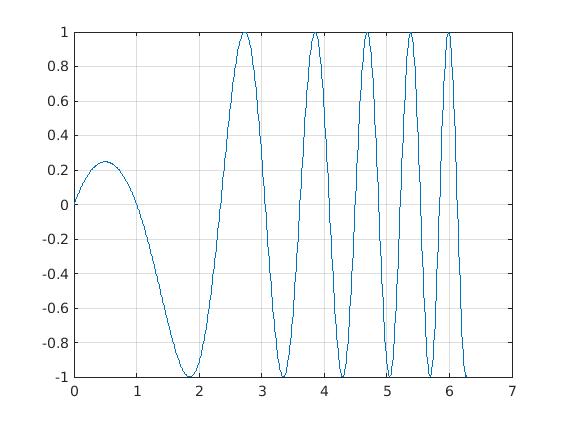

% b
x = 0:0.01:2*pi;
y = sin(x.*(1-x));
plot(x,y);
grid on;

z = ginput(1);


r = fzero(@(x) sin(x*(1-x)), z(1));
disp(r);

    3.0560



%c
syms u
f = u*sin(u)-cos(u);
r = vpasolve(f, u, [0,pi]);

disp(r);

$$0.86033358901937976248389342413766$$

%d
syms u
f = (sin(u))^2 + (0.5-1/u)*cos(u)-0.5;
r = vpasolve(f, u, [pi/2,3*pi]);
disp(r);

$$8.4264373258601437584569670589285$$

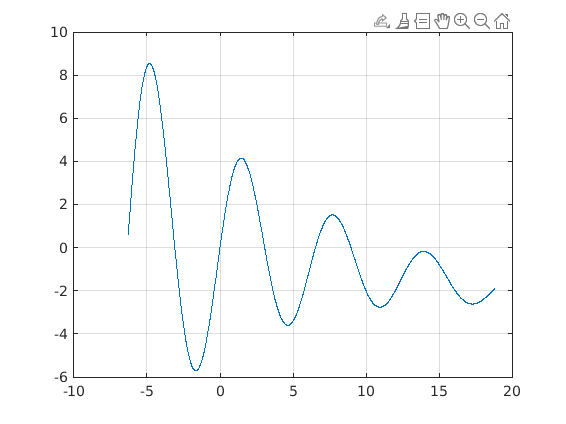

%e
x = -2*pi:0.01:6*pi;
y = 5*exp(-0.1*x).*sin(x)-0.1.*x;
plot(x, y);
grid on;

z = ginput(1);


r = fzero(@(x) 5*exp(-0.1*x)*sin(x)-0.1*x, z(1));
disp(r);

    3.0584



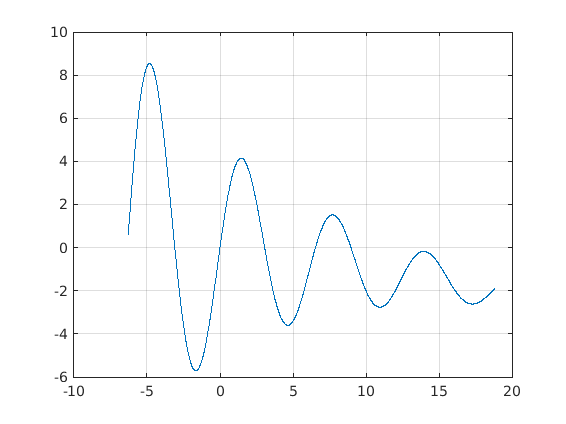

%f
n = input("Please type in the 'n'");

syms u;
f = u^n-1;
r = solve(f,u);
disp(r);

$$\left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

% 4
r = fzero(@(x)x^2+1, -1);

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at 1.7162e+154 is Inf.)
Check function or try again with a different starting value.


disp(r);

   NaN




syms u;
f = u^2+1;
r = solve(f,u);
disp(r);

$$\left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

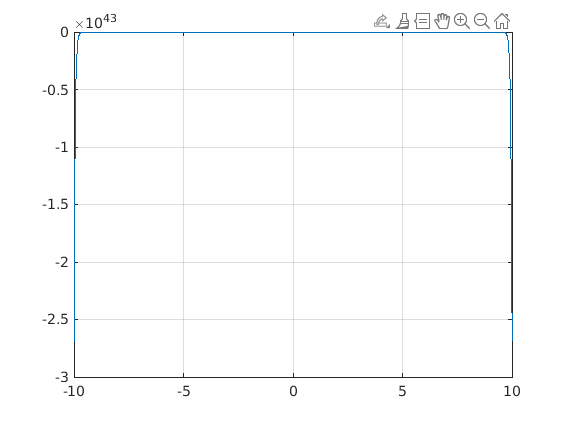

%5
x = -10:0.01:10;
y = cos(x)-exp(0.001+x.^2);
plot(x,y);
grid on;

z = ginput(1);


r = fzero(@(x) cos(x)-exp(0.001+x^2), z(1));

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -32.4301 is -Inf.)
Check function or try again with a different starting value.


disp(r);

   NaN




syms u;
f = cos(u)-exp(0.001+u^2);
r = solve(f,u);

disp(r);

    3.4865



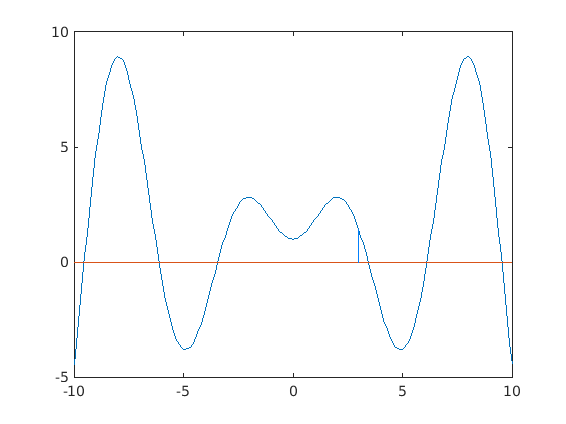

% Задача 1 Метод Ньютона
%input(a);
%input(b);
a = -10; b = 10; eps = 0.001;

h = 0.1;
iter = 100;
x = a:0.1:b;
y = 1 + x.*sin(x);
plot(x,y);
hold on;
plot(x, x*0);
z = ginput(1);
z = z(1);
for i = 1:iter
    line([z,z],[0, 1+z*sin(z)], 'Color', [i/100, 0.5, 1-i/100]);
    hold on;
    x = z-1:0.1:z+1;
    y = (x-z)*((z+h)*sin(z+h)-(z)*sin(z))/h+1+z*sin(z);
    plot(x,y, 'Color', 'red');
    hold on;
    k = z - h*(1+z*sin(z))/((z+h)*sin(z+h)-(z)*sin(z));
    plot(z,1+z*sin(z),'.','MarkerSize', 10);
    hold on;
    plot(k, 1+k*sin(k), '.','MarkerSize', 10);
    hold on;
    z = k;
    hold on;
    if abs(1+k*sin(k)) < eps
        break;
    end
end
disp(k);
hold off;
%r = fzero(@(x) 1+sin(x), z);
%disp(r);

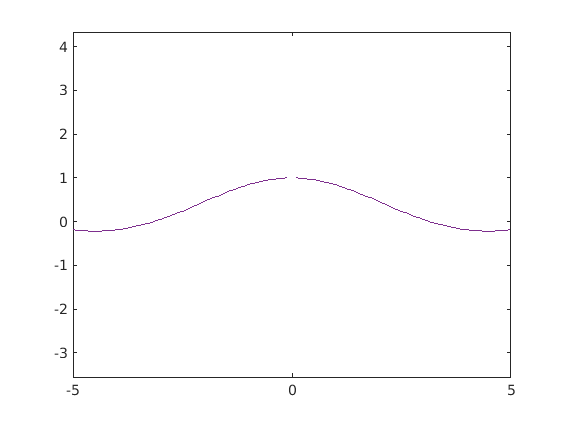

   -2.8961



%Задача 1 Метод деления интервала пополам
x = -5:0.1:5;

y = sin(x)./x;
eps = 0.001;
iter = 100;
plot(x,y);
axis equal;   
hold on;
plot(x, y*0);
hold on;
grid on;
[z1, z2] = ginput(2);
z1 = z1(1); z2 = z2(1);
if (sign(sin(z1)/z1) == sign(sin(z2)/z2) && sign(sin((z1+z2)/2)/(z1+z2)/2) == sign(sin(z2)/z2) && sign(sin((z1+z2)/2)/(z1+z2)/2) == sign(sin(z1)/z1))
    plot(z1,sin(z1)/z1,'.','MarkerSize', 10);
    hold on;
    plot((z1+z2)/2,sin((z1+z2)/2)/(z1+z2)/2,'.','MarkerSize', 10);
    hold on;
    plot(z2,sin(z2)/z2,'.','MarkerSize', 10);
    hold on;
    disp("Wrong points")
else
    for i = 1:iter
        plot(z1,sin(z1)/z1,'.','MarkerSize', 10);
        hold on;
        plot((z1+z2)/2,sin((z1+z2)/2)/(z1+z2)/2,'.','MarkerSize', 10);
        hold on;
        plot(z2,sin(z2)/z2,'.','MarkerSize', 10);
        hold on;
        x = (z1+z2)/2;
        if abs(sin(x)/x) < eps
            break;
        end
        if sign(sin(x)/x) == sign(sin(z2)/z2)
            z2 = x;
        else
            z1 = x;
        end
    end
    disp(x);
    disp(sin(x)/x);
    disp(i);
end
hold off;